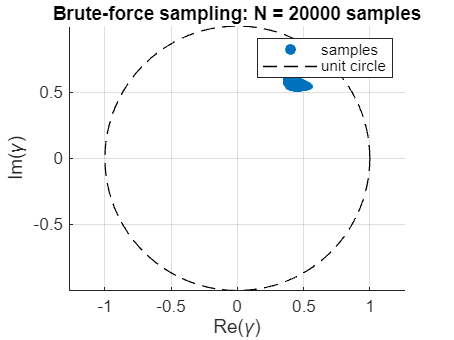

% T11 is the polametric covariance matrix for image 1
T11 = [ 0.05847998335958+(-0.00000000003436i),  0.02322549000382+( 0.00412032753229i), -0.00373708992265+(-0.00653817877173i);
        0.02322549000382+(-0.00412032753229i),  0.03677463904023+(-0.00000000000372i),  0.00064645201201+(-0.00277991150506i);
       -0.00373708992265+( 0.00653817877173i),  0.00064645201201+( 0.00277991150506i),  0.02596748620272+(-0.00000000002635i) ];
% Likewise T22 is for image 2
T22 = [ 0.05689823627472+(-0.00000000001034i), 0.02104423381388+( 0.00422748271376i), -0.00340018770657+( 0.00145383051131i);
        0.02104423381388+(-0.00422748271376i), 0.03230445459485+(-0.00000000002282i), -0.00061244174140+( 0.00046341505367i);
       -0.00340018770657+(-0.00145383051131i), -0.00061244174140+(-0.00046341505367i), 0.03185206279159+(-0.00000000002684i) ];
% O12 is the cross correlation between image 1 and 2
O12 = [ 0.02365791425109+( 0.03072485886514i), 0.00852214731276+( 0.01354217156768i),  0.00096822343767+(-0.00140193325933i);
        0.01268068421632+( 0.00936379563063i), 0.01849138364196+( 0.01861595176160i),  0.00019080555649+(-0.00004700790305i);
       -0.00330265238881+(-0.00118652079254i), -0.00166627962608+( 0.00078822940122i), 0.01114138867706+( 0.01753164269030i) ];

% Regularize diagonals if very small (avoid divide-by-zero)
eps_reg = 1e-12;
T11 = (T11 + T11')/2;
T22 = (T22 + T22')/2;
T11 = T11 + eps_reg*trace(T11)/3 * eye(3);
T22 = T22 + eps_reg*trace(T22)/3 * eye(3);

% Precompute for speed if needed
% We'll compute gamma(w) directly for many w vectors:
N = 20000; % number of random polarization samples (adjust)
gamma_vals = complex(zeros(N,1));
%3xN matrix
w_store = complex(zeros(3,N));

% sample w uniformly on complex unit sphere
%We dont need to check for repeated samples, because we are sampling from a
%continious distribution. So statistaclly we should not get identical
%samples.
for k = 1:N
    % randn(3,1) creates three random normally distrubited numbers, so that
    % we are uniform on the complex sphere.
    z = (randn(3,1) + 1i*randn(3,1));
    %Normalize
    w = z / norm(z);
    %Store the value
    w_store(:,k) = w;
    %Calculate numerator
    num = w' * O12 * w;
    %Calculate denomerator
    denom = sqrt((w' * T11 * w) * (w' * T22 * w));
    %calculate gamma and store it
    gamma_vals(k) = num / denom;
end

% --- Plot the brute-force sampled points ---
figure('Name','Brute-force coherence sampling','NumberTitle','off');
scatter(real(gamma_vals), imag(gamma_vals), 8, 'filled'); axis equal; grid on;
xlabel('Re(\gamma)'); ylabel('Im(\gamma)');
title(sprintf('Brute-force sampling: N = %d samples', N));
% draw unit circle for reference
hold on; th = linspace(0,2*pi,500); plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
legend('samples','unit circle');